# Full Sim Experiment 

motorRes = [.4 .4 .4 .4];
load params/batteryParams.mat;
load params/Q_coef;
global batteryParams;

% original battery capacitance
Q_orig = 3.8712;

% iterations
k      = 375;

% voltage profiles
v{k,1} = [];

% soc profiles
z{k,1} = [];

% current profiles
c{k,1} = [];

% power profiles
p{k,1} = [];

% ss power vals
pows   = zeros(1,k);

% final landing position  <-- system performance parameter (but no position
% controller, so this gets off very quickly)
posf   = zeros(2,k);

% total power consumption <-- system performance parameter
powt   = zeros(1,k);

% motor resistance vals
mval   = zeros(1,k);

% final soc               <-- system performance parameter (if the
% remaining soc after 50% of the mission goes below a certain threshold,
% then the uav can't return)
soce   = zeros(1,k);

% battery capacitance vals
Qa     = zeros(1,k);

% estimated capacitance
Qe     = Qa;

% predicted capacitance
Qp     = Qa;

% ss rpm
rpms   = zeros(1,k);

% estimated rpm
RPMe   = rpms;

% predicted rpm
RPMp   = rpms;

% rpm residual
rpmr   = rpms;

% battery residual
batr   = Qa;

% prediction horizon
horizon = 10;

% to save eol vals (set in loop)
eolBatt = 1;
eolMot  = 1;
eolSys  = 1;

% battery prediction/estimation variables
maintWarnBatt = 1;
maintNoticeBatt = false;
failWarnBatt = 1;
failNoticeBatt = false;

maintThreshBatt = 3.48;
failThreshBatt  = 3.0922;

maintFlagBatt = false;
failFlagBatt  = false;

% motor prediction/estimation variables
maintWarnMot   = 1;
maintNoticeMot = false;
failWarnMot    = 1;
failNoticeMot  = false;

% set on first iteration
maintThreshMot = 1;
failThreshMot  = 1;
setRPM         = 1;

maintFlagMot = false;
failFlagMot  = false;

time = 0;

f = waitbar(0, 'simulation starting...');
tic
for i = 1:k
    
    % -------------------- progress bar ----------------------
    waitbar(round((i/k), 2),f, {['simulation in progress, iteration: ' num2str(i) ', elapsed time: ' num2str(time)], ...
        ['ssrpm: ' num2str(rpms(i)) ' final soc: ' num2str(soce(i)) ' power: ' num2str(powt(i))]});
    % --------------------------------------------------------
    
    % execute the simulation
    sim('MavicProComplete_oct22');
    
    % save some variables
    v{i}  = v_batt_hat.Data;
    z{i}  = soc_hat.Data;
    c{i}  = i_batt.Data;
    p{i}  = power.Data;
    time  = time + tout(end);
    
    % get steady state power consumption
    pows(i) = power.Data(uint16(length(tout)/2));
    
    % get total power consumption
    powt(i) = sum(power.Data);
    
    % add the motor resistance to the list
    mval(i) = motorRes(1);
    
    % get the final SOC 
    soce(i) = soc_hat.Data(end);
    
    % track the rpm and current consumption residuals
    rpmr(i) = sum(rpm_res.Data.^2);
    batr(i) = sum(r.Data.^2);
    
    % get the final position
    posf(:,i) = [round(pos(end,1),1), round(pos(end,2),1)];
    
    % add the current capacitance to the list
    Qa(i) = batteryParams.Q;
    
    % get the steady state rpm
    rpms(i) = rpm.Data(uint16(length(tout)/2));
    
    % use the steady state rpm in the first run as the setRPM (nominal)
    if i == 1
        setRPM = rpms(i);
        maintThreshMot = .95 * rpms(i);
        failThreshMot  = .9 * rpms(i);
    end
   
    % update the degradation parameters according to their degredation
    % functions
    batteryParams.Q  = polyval(Q_coef, i);
    motorRes(1) = motorRes(1) + .001;
    
    % sample the rpm and capacitance from a normal distribution 
    RPMe(i) = normrnd(rpms(i), 30);
    Qe(i) = normrnd(Qa(i), .03);
       
    save('params/batteryParams.mat', 'batteryParams');
   
    if i >= horizon
        x = ((i-(horizon-1)):1:i)';
        
        % --------------------------------- Battery -----------------------
        % fit a linear curve for estimation using the sampled capacitance
        q_poly = polyfit(x, smoothdata(Qe((i-(horizon-1)):i)', 'rlowess', 5), 1);
 
        % for plotting
        q_pred = polyval(q_poly, i+5);
        Qp(i) = q_pred;
        
        % for prediction
        q_pred = polyval(q_poly, i+horizon);
        
        % threshold checking ----------------------------------------------
        if ~maintFlagBatt && q_pred <= maintThreshBatt
            maintFlagBatt = true;
            maintWarnBatt = i;
            disp(["Battery Maintenance threshold will be reached at cycle: "  num2str(i+horizon)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~maintNoticeBatt && Qe(i) >= .995*maintThreshBatt && Qe(i) <= 1.01*maintThreshBatt
            maintNoticeBatt = true;
            disp(["Battery Maintenance Required. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if ~failFlagBatt && q_pred <= failThreshBatt
            failFlagBatt = true;
            failWarnBatt = i;
            disp(["Battery Failure threshold will be reached at cycle: "  num2str(i+horizon)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~failNoticeBatt && Qe(i) >= .995*failThreshBatt && Qe(i) <= 1.01*failThreshBatt
            failNoticeBatt = true;
            disp(["Estimated battery failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if Qa(i) <= failThreshBatt
            disp(["Actual battery failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
            eolBatt = i;
            break
        end

        % --------------------------------- Motor -----------------------
        
        % fit a linear curve for estimation using the sampled rpm data
        p_rpm = polyfit(x, smoothdata(RPMe((i-(horizon-1)):i)', 'rlowess', 15), 1);
        
        % for plotting
        RPMp(i) = polyval(p_rpm, i+5);
        
        % for prediction
        rpm_pred = polyval(p_rpm, i+horizon);
        
        % threshold checking ------------------------------------------
        if ~maintFlagMot && rpm_pred <= maintThreshMot
            maintFlagMot = true;
            maintWarnMot = i;
            disp(["Motor Maintenance threshold will be reached at cycle: "  num2str(i+horizon)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~maintNoticeMot && RPMp(i) >= .995*maintThreshMot && RPMp(i) <= 1.01*maintThreshMot
            maintNoticeMot = true;
            disp(["Motor Maintenance Required. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if ~failFlagMot && rpm_pred <= failThreshMot
            failFlagMot = true;
            failWarnMot = i;
            disp(["Motor Failure threshold will be reached at cycle: "  num2str(i+horizon)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~failNoticeMot && RPMp(i) >= .995*failThreshMot && RPMp(i) <= 1.01*failThreshMot
            failNoticeMot = true;
            disp(["Estimated Motor failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if rpms(i) <= failThreshMot
            disp(["Actual Motor failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
            eolMot = i;
            break
        end

        % --------------------------------- System -----------------------
        
        
    end
end
toc

pgon = polyshape([failWarnMot failWarnMot eolMot eolMot], [rpms(failWarnMot)-8 rpms(failWarnMot)+8 rpms(eolMot)+8 rpms(eolMot)-8]);
motorResults.setRPM   = setRPM;
motorResults.rpms     = rpms;
motorResults.mvals    = mval;
motorResults.RPMe     = RPMe;
motorResults.RPMpreds = RPMp;
motorResults.eol      = eolMot;
motorResults.pgon     = pgon;
motorResults.rpmr     = rpmr;

motorResults.failThresh  = failThreshMot;
motorResults.failWarn    = failWarnMot;
motorResults.maintWarn   = maintWarnMot;
motorResults.maintThresh = maintThreshMot;


save('motorResults.mat', 'motorResults');

pgon = polyshape([failWarnBatt failWarnBatt eolBatt eolBatt], [Qa(failWarnBatt)+.03 Qa(failWarnBatt)-.03 Qa(eolBatt)-.03 Qa(eolBatt)+.03]);
batteryResults.Qe    = Qe(1:eolBatt);
batteryResults.Qp = Qp(1:eolBatt);
batteryResults.Qa    = Qa(1:eolBatt);
batteryResults.pgon  = pgon;
batteryResults.eol   = eolBatt;
batteryResults.v     = v;
batteryResults.z     = z;
batteryResults.batr  = batr;

batteryResults.maintWarn   = maintWarnBatt;
batteryResults.failWarn    = failWarnBatt;
batteryResults.maintThresh = maintThreshBatt;
batteryResults.failThresh  = failThreshBatt;

batteryParams.Q  = Q_orig;
save('batteryResults.mat', "batteryResults");
save('params/batteryParams.mat', 'batteryParams');

close(f);

disp("mission took: " + num2str(tout(end)) + "seconds");
disp("rpm residual: " + num2str(mean(rpm_res/100)));
disp("final position: " + num2str(round(pos(end,1),1)) + "," + num2str(round(pos(end,2),1)));
disp("soc: " + num2str(soc.Data(end)));

## Prognostic Experiment Plots

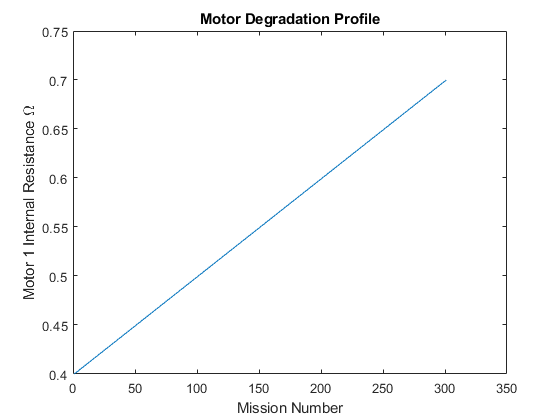

plot(mval(1:eolBatt));
title("Motor Degradation Profile");
xlabel("Mission Number");
ylabel("Motor 1 Internal Resistance {\Omega}")

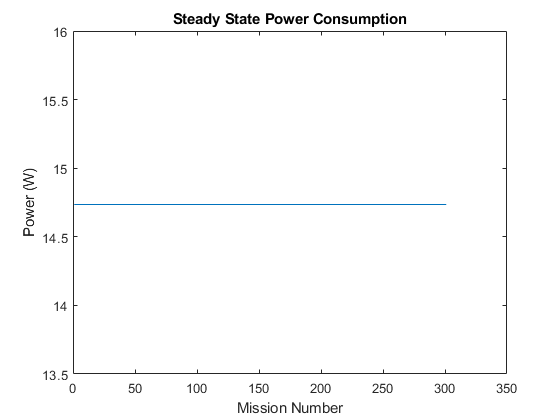

plot(pows(1:eolBatt));
title("Steady State Power Consumption");
xlabel("Mission Number")
ylabel("Power (W)");

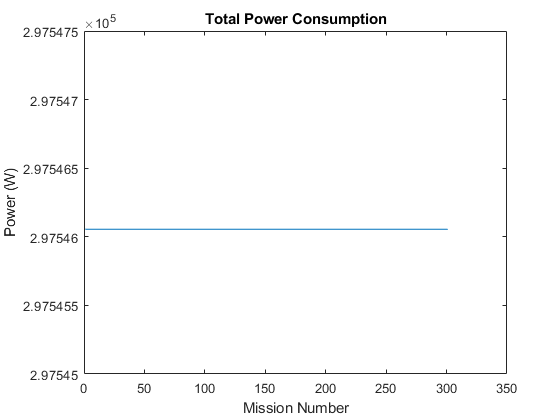

plot(powt(1:eolBatt));
title("Total Power Consumption");
xlabel("Mission Number");
ylabel("Power (W)");

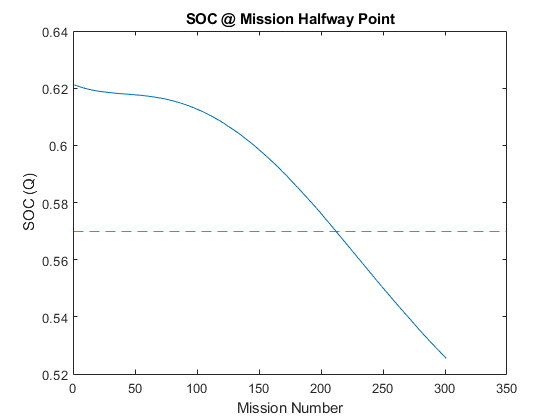

plot(soce(1:eolBatt));
title("SOC @ Mission Halfway Point");
yline(.57, 'r--');
xlabel("Mission Number");
ylabel("SOC (Q)");

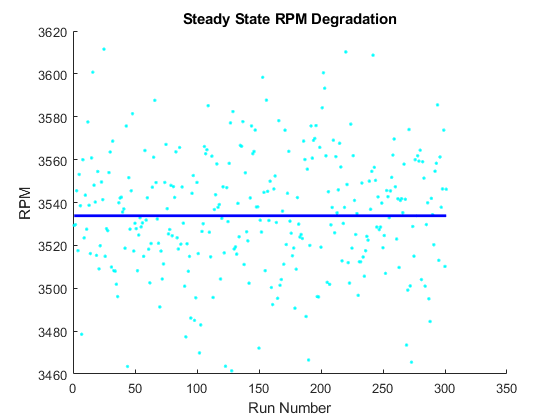

eolMot = 301;
fmot = figure(100); clf; 
hold on;
plot(RPMe(1:eolMot), 'c.');
%plot([20:1:eolMot]',smoothdata(RPMp(20:eolMot), 'movmean', 15), 'linew', 2);
plot(rpms(1:eolMot), 'b', 'linew', 2);
%pgon = polyshape([failWarnMot failWarnMot eolMot eolMot], [rpms(failWarnMot)-8 rpms(failWarnMot)+8 rpms(eolMot)+8 rpms(eolMot)-8]);
%plot(pgon, 'FaceColor', 'yellow', 'FaceAlpha', .89, 'EdgeColor', 'none');
%plot(maintWarnMot+40, rpms(maintWarnMot+40), 'ko', 'linew', 3);
%plot(failWarnMot, rpms(failWarnMot), 'mo', 'linew', 2);
%plot(failWarnMot+40, rpms(failWarnMot+37), '*', 'MarkerSize', 12);
%plot(eolMot, rpms(eolMot), 'ro', 'linew', 2);
hold off;
title("Steady State RPM Degradation");
xlabel("Run Number");
ylabel("RPM");

%legend(["RPM Samples", "RPM Estimate", "Actual RPM", "Prediction Horizon", "Maintenance Warning", "Failure Warning", "Estimated EOL", "EOL"], 'location', 'southwest');

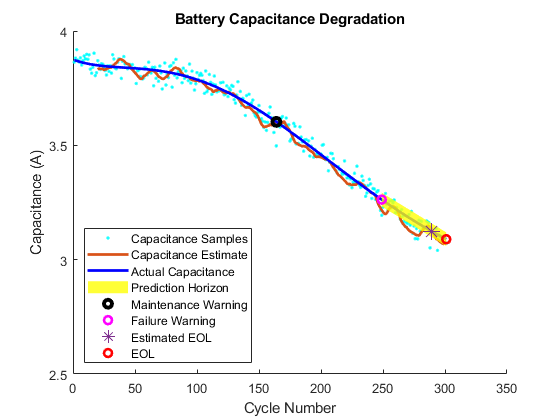

fbat = figure(101); clf;
hold on;
plot(Qe(1:eolBatt), 'c.');
plot([20:1:eolBatt]',smoothdata(Qp(20:eolBatt), 'movmean', 10), 'linew', 2);
plot(Qa(1:eolBatt), 'b', 'linew', 2);
pgon = polyshape([failWarnBatt failWarnBatt eolBatt eolBatt], [Qa(failWarnBatt)+.03 Qa(failWarnBatt)-.03 Qa(eolBatt)-.03 Qa(eolBatt)+.03]);
plot(pgon, 'FaceColor', 'yellow', 'FaceAlpha', .79, 'EdgeColor', 'none');
plot(maintWarnBatt, Qa(maintWarnBatt), 'ko', 'linew', 3);
plot(failWarnBatt, Qa(failWarnBatt), 'mo', 'linew', 2);
plot(failWarnBatt+40, Qa(failWarnBatt+40), '*', 'MarkerSize', 12);
plot(eolBatt, Qa(eolBatt), 'ro', 'linew', 2);
hold off;
%set(get(get(s, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
title("Battery Capacitance Degradation");
xlabel("Cycle Number");
ylabel("Capacitance (A)");
ylim([2.5 4]);
legend(["Capacitance Samples", "Capacitance Estimate", "Actual Capacitance", "Prediction Horizon", "Maintenance Warning", "Failure Warning", "Estimated EOL", "EOL"], 'location', 'southwest');

## Single Run Plots

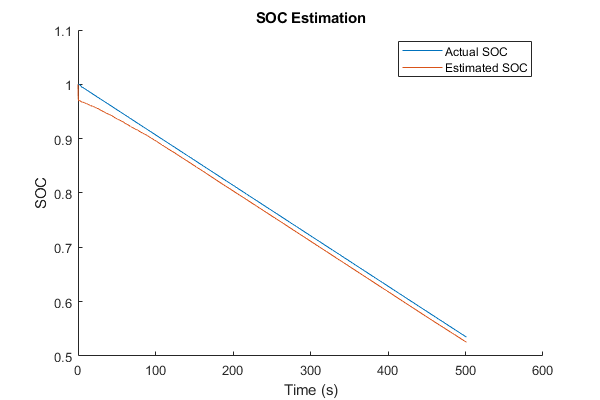

f1 = figure(1); clf;
set(gcf, 'Position', [0 0 600 400]);
hold on;
plot(soc.Time, soc.Data);
plot(soc_hat.Time, soc_hat.Data);
title("SOC Estimation");
legend(["Actual SOC", "Estimated SOC"]);
ylabel("SOC");
xlabel("Time (s)");
hold off;

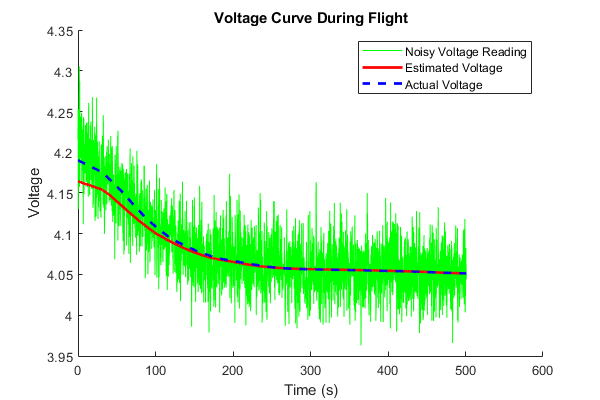

f2 = figure(2); clf;
hold on;
plot(noisy_v.Time, noisy_v.Data, 'g');
plot(v_batt_hat.Time, smoothdata(v_batt_hat.Data, 'movmean', 500), 'r', 'linewidth', 2);
plot(v_batt.Time, smoothdata(v_batt.Data, 'movmean', 500), 'b--', 'linewidth', 2);
hold off;
title("Voltage Curve During Flight");
xlabel("Time (s)");
ylabel("Voltage");
legend(["Noisy Voltage Reading", "Estimated Voltage", "Actual Voltage"]);

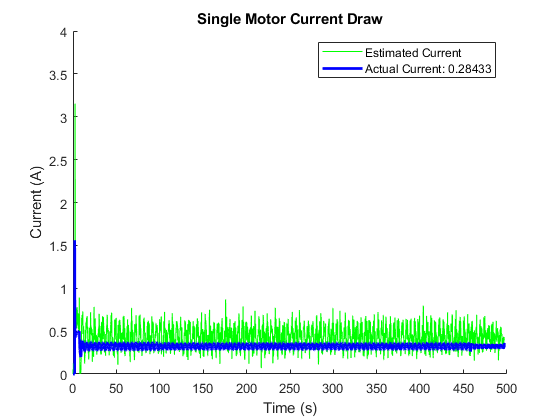

i_hatData = i_hat.Data(1,:);
f3 = figure(3); clf;
hold on;
plot(i_hat.Time, i_hatData, 'g');
plot(i_mot.Time, i_mot.Data, 'b', 'linewidth', 2);
hold off;
title("Single Motor Current Draw");
xlabel("Time (s)");
ylabel("Current (A)");
legend(["Estimated Current", "Actual Current: " + num2str(i_mot.Data(1000))]);
ylim([0 4]);

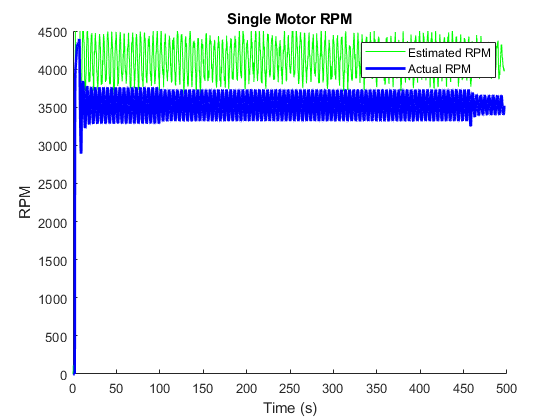

f4 = figure(4); clf;
hold on;
plot(rpm_hat.Time, rpm_hat.Data, 'g');
plot(rpm.Time, rpm.Data, 'b', 'linewidth', 2);
hold off;
xlabel("Time (s)");
ylabel("RPM");
ylim([0 4500]);
title("Single Motor RPM");
legend(["Estimated RPM", "Actual RPM"]);

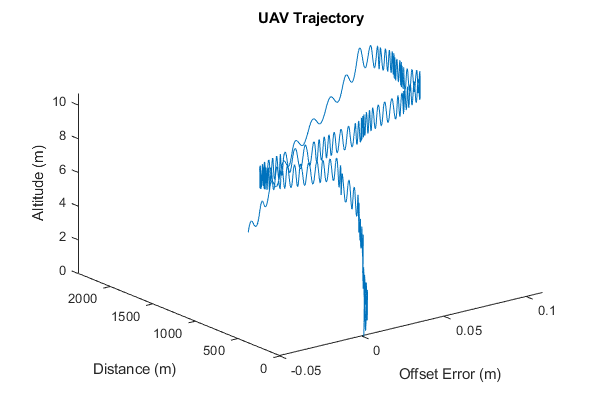

f5 = figure(5); clf;
set(gcf, 'Position', [0 0 600 400]);
plot3(pos(:,1), pos(:,2), pos(:,3));
%xlim([-1 1]);
xlabel("Offset Error (m)");
ylabel("Distance (m)");
zlabel("Altitude (m)");
title("UAV Trajectory");

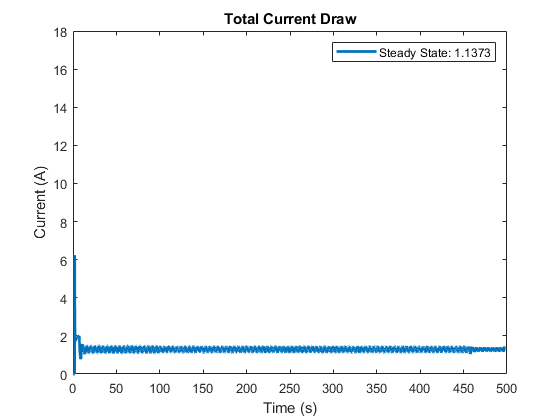

f6 = figure(6); clf;
plot(i_batt.Time, i_batt.Data, 'linewidth', 2);
title("Total Current Draw");
xlabel("Time (s)");
ylim([0 18]);
ylabel("Current (A)");
legend(["Steady State: " + num2str(i_batt.Data(1000))]);

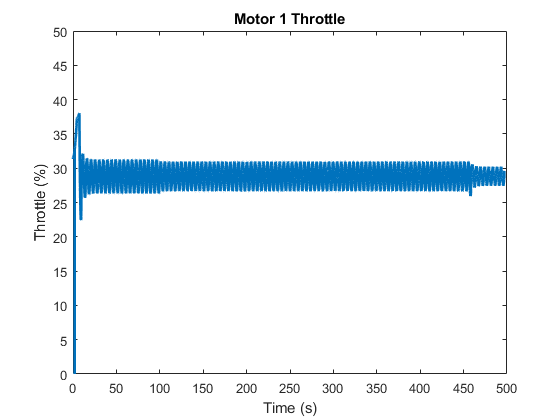

f7 = figure(7); clf;
plot(m1_throttle.Time, m1_throttle.Data, 'linewidth', 2);
title("Motor 1 Throttle");
xlabel("Time (s)");
ylabel("Throttle (%)");
ylim([0 50]);

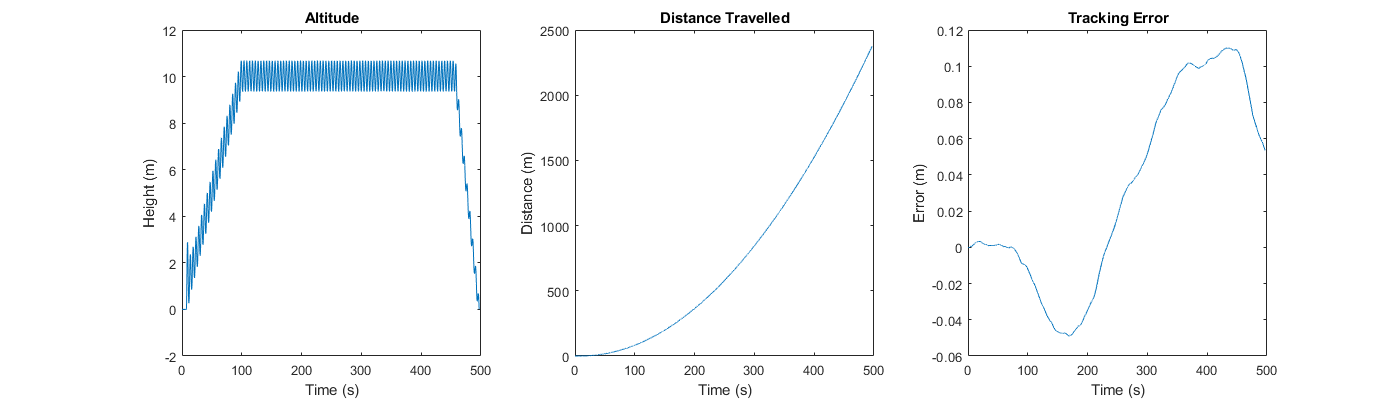

f8 = figure(8); clf;
set(gcf, 'Position', [0 0 1400 400]);
subplot(131);
plot(tout, pos(:,3));
title("Altitude");
xlabel("Time (s)");
ylabel("Height (m)");
subplot(132);
plot(tout, pos(:,2));
title("Distance Travelled");
xlabel("Time (s)");
ylabel("Distance (m)");
subplot(133);
plot(tout, pos(:,1));
title("Tracking Error");
xlabel("Time (s)");
ylabel("Error (m)");

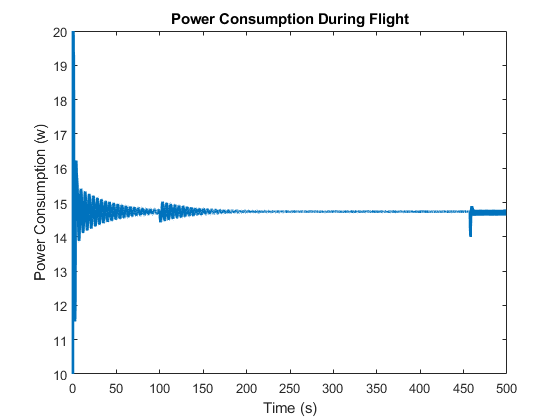

f10 = figure(10); clf;
set(gcf, 'Resize', 'On');
plot(power.Time, power.Data, 'linew', 2);
title("Power Consumption During Flight");
xlabel("Time (s)");
ylabel("Power Consumption (w)");
ylim([10 20]);

w = warning('off', 'all');
window = [501:1500];
flag = true;
motorRes = [.4 .4 .4 .4];
err = 0;
zs = zeros(1000,5);
pwrs = zs;
for i = 1:5
    while flag
        try
           sim("MavicProComplete_oct22.slx");
            flag = false;
        catch ME
            disp('caught error');
            motorRes = motorRes + .01;
            err = err + 1;
            if err > 100
                break
            end
        end
    end 
    zs(1:1000,i) = pos(window,3);
    pwrs(1:1000,i) = power.Data(window);
    motorRes = motorRes + .2;
    flag = true;
end

Found algebraic loop containing: 
MavicProComplete_oct22/Quadcopter/Powertrain/motorGroup/BLDC Motor4/throttle_fcn/Product2 (algebraic variable)
MavicProComplete_oct22/Quadcopter/Powertrain/motorGroup/BLDC Motor4/throttle_fcn/Product
MavicProComplete_oct22/Quadcopter/Powertrain/motorGroup/BLDC Motor4/Sum1
MavicProComplete_oct22/Quadcopter/Powertrain/motorGroup/BLDC Motor4/Divide1


caught error


Found algebraic loop containing: 
MavicProComplete_oct22/Quadcopter/Powertrain/motorGroup/BLDC Motor4/throttle_fcn/Product2 (algebraic variable)
MavicProComplete_oct22/Quadcopter/Powertrain/motorGroup/BLDC Motor4/throttle_fcn/Product
MavicProComplete_oct22/Quadcopter/Powertrain/motorGroup/BLDC Motor4/Sum1
MavicProComplete_oct22/Quadcopter/Powertrain/motorGroup/BLDC Motor4/Divide1


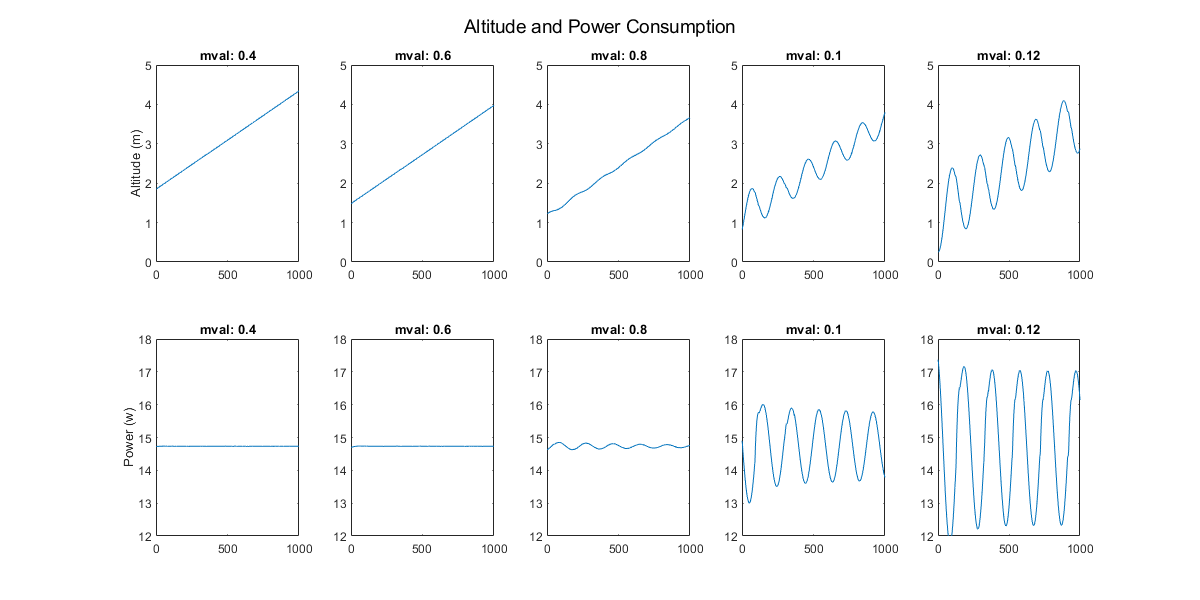

f31 = figure(31); clf;
f31.Position = [0 0 1200 600];
mvals = [.4 .6 .8 .1 .12];
for i = 1:5
    subplot(2,5,i);
    plot(zs(:,i));
    ylim([0 5]);
    title("mval: " + num2str(mvals(i)));
    if i == 1
        ylabel("Altitude (m)");
    end
    subplot(2,5,i+5);
    plot(pwrs(:,i));
    ylim([12 18]);
    if i == 1
        ylabel("Power (w)");
    end
    title("mval: " + num2str(mvals(i)));
end
sgtitle("Altitude and Power Consumption");

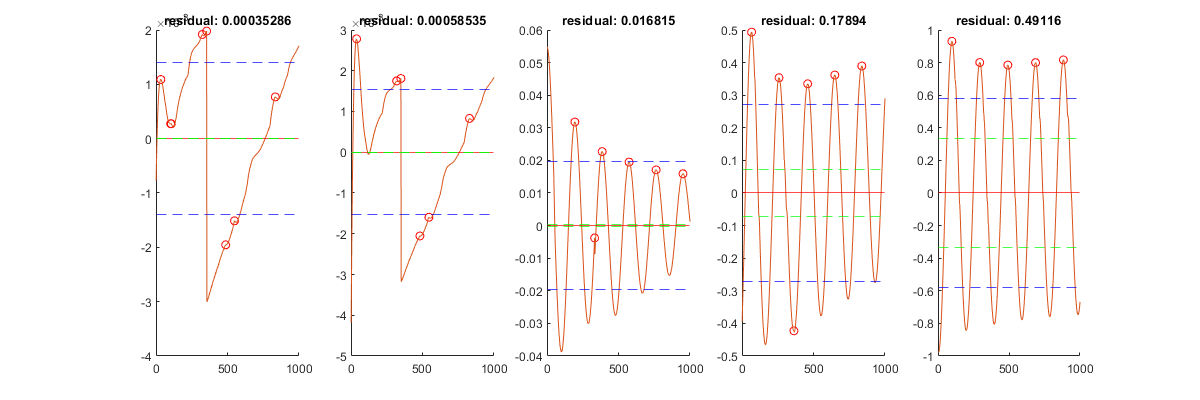



f30 = figure(30); clf;
f30.Position = [0 0 1200 400];
res = zeros(5,1);
for i = 1:5
    mu = mean(detrend(zs(:,i)));
    vr = var(detrend(zs(:,i)));
    
    [pks, locs] = findpeaks(detrend(zs(:,i)));
    subplot(1,5,i);
    hold on;
    yline(mu, 'r');
    yline(mu+vr,'g--');
    yline(mu-vr, 'g--');
    yline(mu+sqrt(vr),'b--');
    yline(mu-sqrt(vr), 'b--');
    plot(locs, pks, 'ro');
    plot(detrend(zs(:,i)));
    hold off;    
    res(i) = abs(mean(pks) - (mu+vr));
    title("residual: " + num2str(res(i)));
end

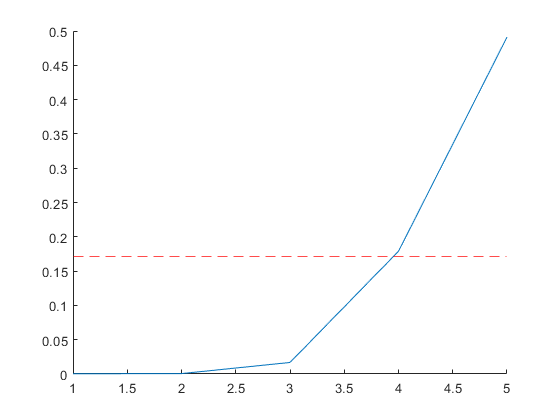

f29 = figure(29); clf;
hold on;
plot(res);
yline(.172, 'r--');